clf

M = [1310 1810 1175 2360 1960 2020 1755 1595 1470 1430 1110 1785];
phi = [10.2 8.1 11.9 5.5 6.8 6.8 7.7 8.9 9.8 10.2 13.2 7.7];

Mbar = 0;
for i = 1:length(M)
    Mbar = Mbar + M(i);
end
Mbar = Mbar / length(M);

fprintf("%f", Mbar);

1648.333333


phibar = 0;
for i = 1:length(phi)
    phibar = phibar + phi(i);
end
phibar = phibar / length(phi);

fprintf("%f", phibar);

8.900000


sumMsquared = 0

sumMsquared = 0

for i = 1:length(M)
    sumMsquared = sumMsquared + (M(i))^2;
end

sumMphi = 0

sumMphi = 0

for i = 1:length(M)
    sumMphi = sumMphi + M(i) * phi(i);
end

n = length(M);

% a = (phibar * sumMsquared - Mbar * sumMphi) / (sumMsquared - n * Mbar^2);
% b = (sumMphi - n * Mbar * phibar) / (sumMsquared - n * Mbar^2);

sumphidM = 0

sumphidM = 0

for i = 1:n
    sumphidM = sumphidM + phi(i) * (-Mbar + M(i));
end

sumMdM = 0

sumMdM = 0

for i = 1:n
    sumMdM = sumMdM + M(i) * (-Mbar + M(i));
end

b = sumphidM / sumMdM;

a = phibar - Mbar * b;

fprintf("phi = %f + %f * M", a, b);

phi = 18.619110 + -0.005896 * M


syms Ms;

phils = @(Ms) a + b * Ms;

sigma = 0;
for i = 1:n
    sigma = sigma + (phi(i) - phils(M(i)))^2;
end
sigma = sqrt(sigma / (n - 2));

fprintf("standard deviation = %f", sigma);

standard deviation = 0.559659

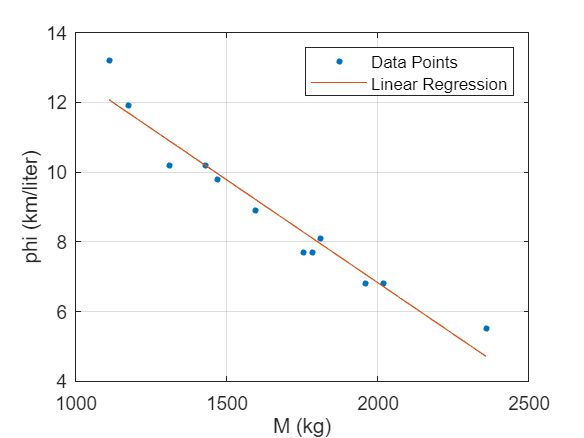


plot(M, phi, '.', "MarkerSize", 10);
hold on
grid on

fplot(phils, [min(M) max(M)]);

legend(["Data Points" "Linear Regression"])
xlabel("M (kg)");
ylabel("phi (km/liter)")